# Load a sample dataset

This example shows how to load a pre-set example fMRI dataset into an fmri_data object.

## General instructions

Before you start, the CANlab_Core_Tools must be added to your path with subfolders. Otherwise, you will get errors.

The script canlab_toolbox_setup can help download and install the toolboxes you need.

Sample datasets are in the "Sample_datasets" folder in CANlab_Core_Tools.

This example will use emotion regulation data in the folder: "Wager_et_al_2008_Neuron_EmotionReg" The dataset is a series of contrast images from N = 30 participants. Each image is a contrast image for [reappraise neg vs. look neg]

These data were published in: Wager, T. D., Davidson, M. L., Hughes, B. L., Lindquist, M. A., Ochsner, K. N.. (2008). Prefrontal-subcortical pathways mediating successful emotion regulation. Neuron, 59, 1037-50.

Here are a couple of helpful functions we will use for display: (you can ignore these.)

dashes = '----------------------------------------------';

printhdr = @(str) fprintf('%s\n%s\n%s\n', dashes, str, dashes);

## Section 1: The quick and easy way to load a pre-specified dataset

The function load_image_set has a number of pre-defined image sets that you can load with one simple command. This is the easiest way to load sample data. The images must be on your Matlab path for this to work.

[data_obj, subject_names, image_names] = load_image_set('emotionreg');

Loaded images:
/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/torwager/Documents/GitHub/CanlabCore


% data_obj is an fmri_data object containing all 30 images.
% subject_names is a list of short names for each image.
% image_names is a list of the full image names with their path.

## Section 2: Manual load. Use filenames to find file names

First, we need to list the file names in a string matrix. Then, we can load them into an fmri_data object We will use the filenames function to get the names, and the fmri_data object constructor function to load the data.

% First, check whether images are on your path:
% We will search for one image and save the path name.

printhdr('Check that we can find data images:')

----------------------------------------------
Check that we can find data images:
----------------------------------------------


myfile = which('con_00810001.img');
mydir = fileparts(myfile);
if isempty(mydir), disp('Uh-oh! I can''t find the data.'), else disp('Data found.'), end

Data found.



% Now we can list all the file names.

printhdr('Find files and get their names:')

----------------------------------------------
Find files and get their names:
----------------------------------------------


image_names = filenames(fullfile(mydir, 'con_008100*img'), 'absolute');
disp('Done.');

Done.



% Now load them into an fmri_data object.

printhdr('Loading the image data into the object:')

----------------------------------------------
Loading the image data into the object:
----------------------------------------------


data_obj = fmri_data(image_names);

Using default mask: /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 5975040 bytes
Loading image number:    30
Elapsed time is 0.339233 seconds.
fmri_data.create: Converting 1203 NaNs to 0s.Image names entered, but fullpath attribute is empty. Getting path info.



% This is the gateway to doing many other things, which are explained in
% other help files.  But just to get us started, let's run through a few
% basic things we can do. We'll mainly just look at some standard plots of
% the data.

## Section 3: Plot the data we just loaded

Operations that we can perform on fmri_data objects are called methods. You can see a list of methods by typing methods(data_obj). Here, we'll call the plot method to visualize the data.

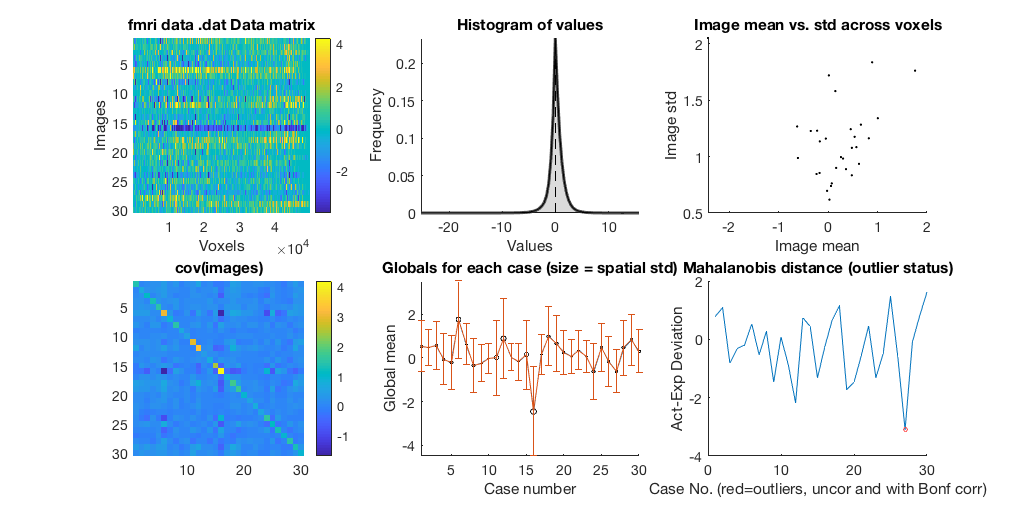

Retained 8 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 46.67%
Expected 1.50 outside 95% ellipsoid, found   1

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 1 images		Cases 27 

Outliers:
Cases after p-value correction: 
Cases, uncorrected:27 

SPM12: spm_check_registration (v6245)              11:17:00 - 03/08/2018
Display /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (

ans = 30×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


plot(data_obj)

snapnow